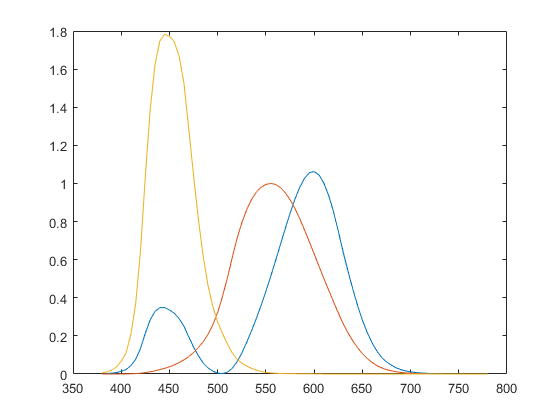

T = load('spectra.mat');
%Blå = x
%röd = grön,y
%gul = z
plot(wavelength,xyz);

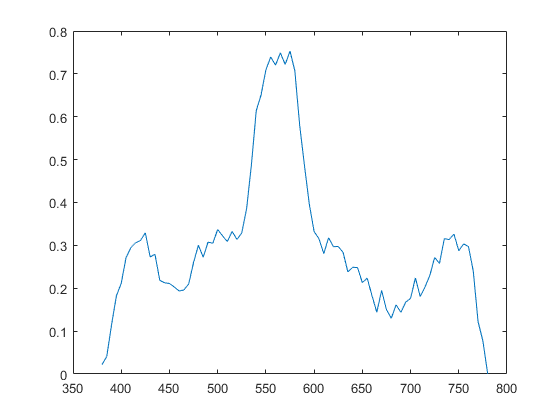

%Skicka in R = 1
[X, Y, Z] = spectra2xyz(1, T.CIED65);


%1.2
%Grönish
plot(wavelength, R1);

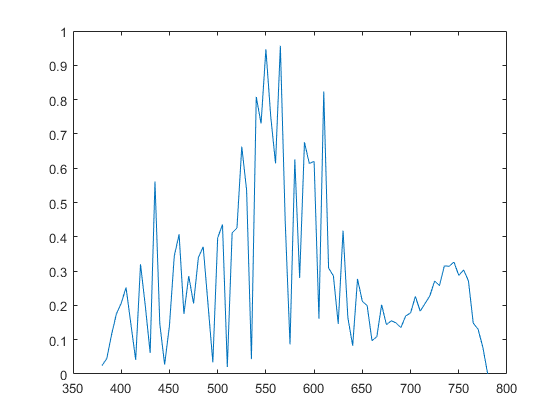

%Turkosish
%Blå=vänster gröm=mitt röd=höger
plot(wavelength, R2);

%R1
[X1, Y1, Z1] = spectra2xyz(R1, T.CIED65);
%R2
[X2, Y2, Z2] = spectra2xyz(R2, T.CIED65);
%Ger samma xyz värden alltså samma färg(upplevs det som)

%1.3
%R1
[X1f, Y1f, Z1f] = spectra2xyz(R1, T.f11);
%R2
[X2f, Y2f, Z2f] = spectra2xyz(R2, T.f11);



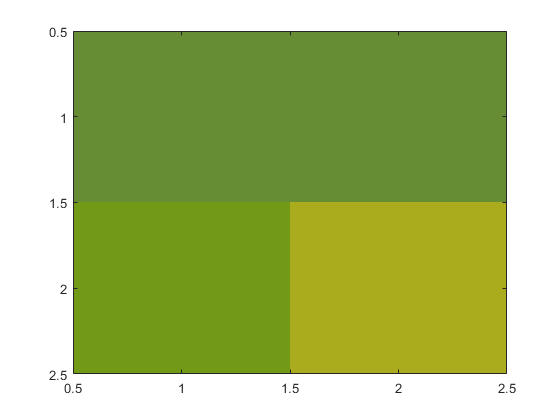

%1.5
[r1, g1, b1] = myxyz2rgb(X1, Y1, Z1);

[r2, g2, b2] = myxyz2rgb(X2, Y2, Z2);

[r1f, g1f, b1f] = myxyz2rgb(X1f, Y1f, Z1f);

[r2f, g2f, b2f] = myxyz2rgb(X2f, Y2f, Z2f);

map = [r1 g1 b1; r2 g2 b2; r1f g1f b1f; r2f g2f b2f];
map = min(1,max(0,map));
image([1 2; 3 4])
colormap(map)
imwrite(colormap(map), 'map.tif');

x1 = (1/(X1+Y1+Z1))*X1; %R1 med CIED65
y1 = (1/(X1+Y1+Z1))*Y1;

x2 = (1/(X2+Y2+Z2))*X2; %R2 med CIED65
y2 = (1/(X2+Y2+Z2))*Y2;

x1f = (1/(X1f+Y1f+Z1f))*X1f; %R1 med f11
y1f = (1/(X1f+Y1f+Z1f))*Y1f;

x2f = (1/(X2f+Y2f+Z2f))*X2f; %R2 med f11
y2f = (1/(X2f+Y2f+Z2f))*Y2f;

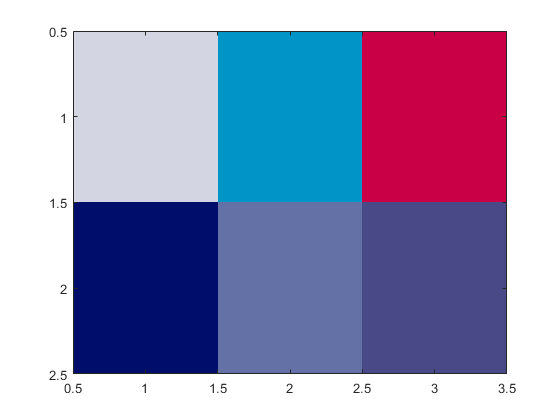

%2.2

[pr, pg, pb] = myxyz2rgb(80.43, 84.00, 96.50);

[cr, cg, cb] = myxyz2rgb(25.84, 42.52, 80.88);

[mr, mg, mb] = myxyz2rgb(37.36, 18.44, 27.52);

[mcr, mcg, mcb] = myxyz2rgb(7.40, 5.74, 40.36);

[onr, ong, onb] = myxyz2rgb(43.915, 44.87, 68.43);

[offr, offg, offb] = myxyz2rgb(31.6, 30.48, 54.2);

map = [pr pg pb; cr cg cb; mr mg mb; mcr mcg mcb; onr ong onb; offr offg offb ];
map = min(1,max(0,map));
image([1 2 3; 4 5 6])
colormap(map)